## 2D concentration map

Creation of a 2D concentration map

dist = [pos.x, pos.y]; % determination of the distance variables to be binned
bin = [0.5 0.5]; % bin width in x and y direction, in mm
mode = 'distance'; % 'distance' is the only possible mode in 2D and 3D
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates bin centers and bin edges of the voxels
 

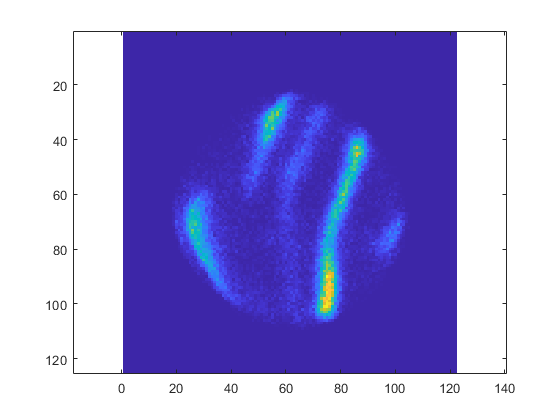

posSpecies = pos(pos.atom == 'C',:); % creation of pos with only desired species
from = 1; % definition of the start index of detected ion
to = 100000; % definition of the end index of detected ion, must be bigger than 'from' value
FDM = hist3([posSpecies.x(from:to), posSpecies.y(from:to)],binCenters); % creates array of the 3D histogram
image = imagesc(FDM); axis equal; % creates image of the field desorption map